### Aero data

Cz_alp = 5.61;
alpha_0 = -0.04;
Cz_delm = 0.13;
Cx_0 = 0.043;
Cm_0 = 0.0135;
Cm_alpha = -2.74;
Cm_q = -38.21;
L = 0.19;
Cm_delm = -0.99;
S = 0.55;
Iy = 1.135;
m = 13.5;
Sprop = 0.2027;
ro = 1.2682;
kMotor = 80;
Cprop = 1;
g = 9.8;
ki = 0.18994/((pi)*2.8956*0.1592);

KV = 0.0659;
KQ = 0.0659;
R = 0.042;
i0 = 1.5;
CQ2 = -0.01664;
CQ1 = 0.00497;
CQ0 = 0.005230;
CT2 = -0.1079;
CT1 = -0.06044;
CT0 = 0.09357;
Di = 0.5;


### Trim calculation

%Trim point calculation
velocity = 25;
Cz_trim= m*g*cos(0)/(0.5*ro*velocity*velocity*S);
alpha_trim = (((Cz_trim + Cz_alp*alpha_0)*(-1*Cm_delm)/Cz_delm) - Cm_0 + (alpha_0*Cm_alpha))/(Cm_alpha + (Cz_alp*(-1*Cm_delm)/Cz_delm));
delta_m_trim = ((alpha_trim - alpha_0)*Cm_alpha + Cm_0)/(-1*Cm_delm);
Cz_trim = Cz_alp*(alpha_trim - alpha_0) + Cz_delm*delta_m_trim;
Cx_trim = Cx_0 + ki*Cz_trim^2;


T_trim =  0.5*ro*velocity*velocity*S*(Cx_trim)

T_trim = 19.9046



syms np
np_trim = solve(ro*Di^4*CT0*np^2/(4*(pi)^2) + (ro*Di^3*CT1*velocity*np/(2*(pi))) + ro*Di^2*CT2*velocity*velocity == T_trim, np);
np_trim = max(np_trim);

syms c 
a = ro*Di^5*CQ0/(2*(pi))^2;
b = ro*Di^4*CQ1*velocity/(2*(pi)) + KQ*KV/R;

c_trim = solve((-b + sqrt(b*b - 4*a*c))/(2*a) == np_trim,c);
syms Vin
Vin_trim = solve(ro*Di^3*CQ2*velocity*velocity - KQ*Vin/R + KQ*i0 == c_trim,Vin);

delt_trim = double(Vin_trim/44.4)

delt_trim = 0.8788

Vin = delt_trim*44.4;
a = ro*Di^5*CQ0/(2*pi)^2;
b = ro*Di^4*CQ1*velocity/(2*pi) + KQ*KV/R;
c = ro*Di^3*CQ2*velocity*velocity - KQ*Vin/R + KQ*i0;
np = (-b + sqrt(b*b - 4*a*c))/(2*a);
T_check = double(ro*Di^4*CT0*np^2/(4*pi^2) + (ro*Di^3*CT1*velocity*np/(2*pi)) + ro*Di^2*CT2*velocity*velocity)

T_check = 19.9046


rad2deg(alpha_trim)

ans = 4.3126

### Pitch controller design

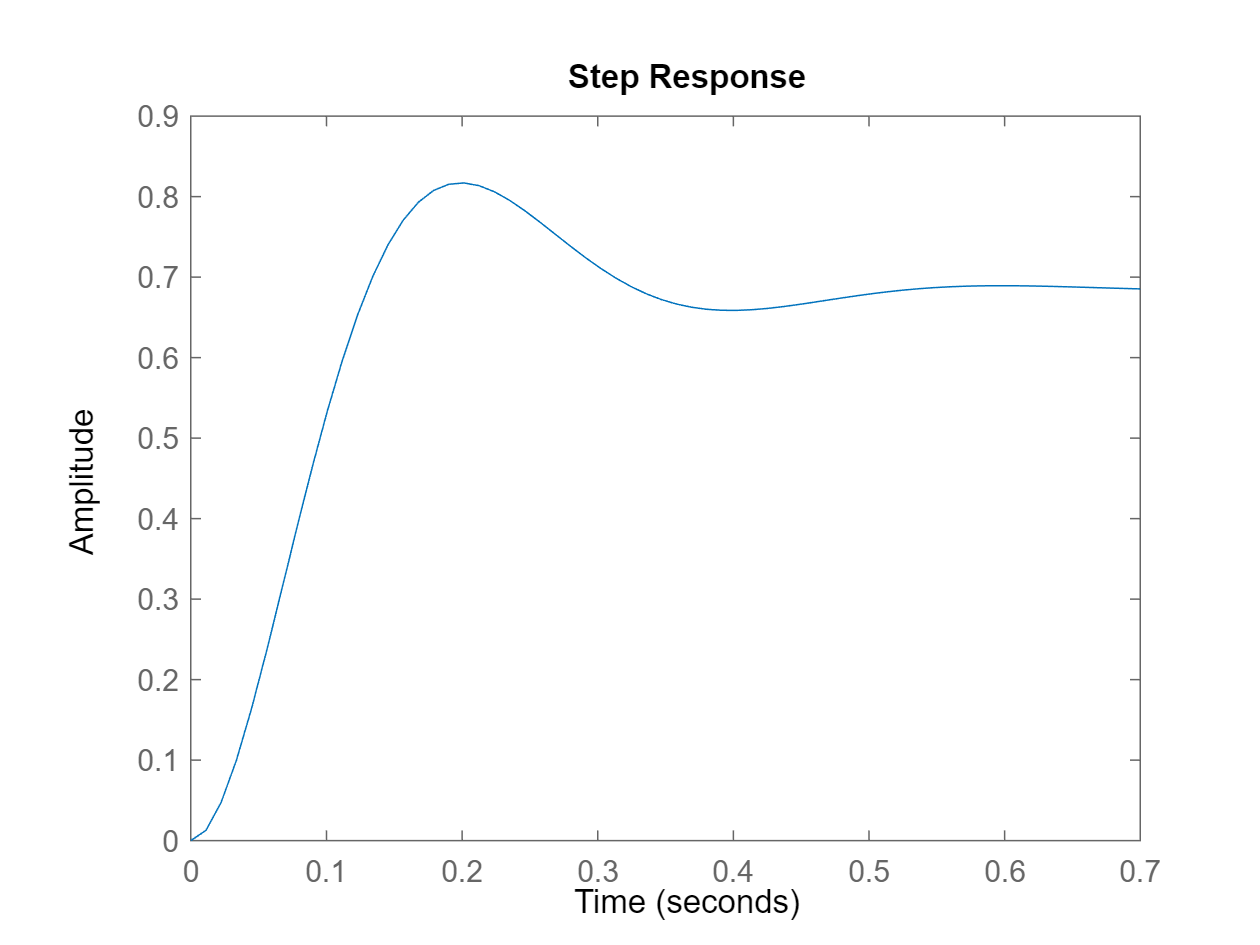

a_theta_1 = -1*(ro*velocity*velocity*L*S/(2*Iy))*Cm_q*(0.5*L/velocity);
a_theta_2 = -1*(ro*velocity*velocity*L*S/(2*Iy))*Cm_alpha;
a_theta_3 = (ro*velocity*velocity*L*S/(2*Iy))*Cm_delm;


wn0 = 15;
%k_p_theta = (wn0*wn0 - a_theta_2)/a_theta_3;
k_p_theta = -45/7.5;
%k_d_theta = (2*0.7*wn0 - a_theta_1)/a_theta_3;
wn0 = sqrt(a_theta_2 - k_p_theta);
k_d_theta = (2*0.8*wn0 - a_theta_1)/a_theta_3;


s = tf('s');
H_q_delta_e = a_theta_3*s/(s^2 + a_theta_1*s + a_theta_2);

CL_H_q_delta_e = H_q_delta_e/(1+k_d_theta*H_q_delta_e);
CL_H_th_delta_e = k_p_theta*(CL_H_q_delta_e/s)/(1+k_p_theta*(CL_H_q_delta_e/s));
step(CL_H_th_delta_e)

### Altitude and vel

K_theta_DC = k_p_theta*a_theta_3/(a_theta_2 + k_p_theta*a_theta_3)

K_theta_DC = 0.6843

%%
Wh = 15; %5-15
wnh = wn0/Wh;

kih = 2*wnh*wnh/(K_theta_DC*velocity);
kph = 2*.8*wnh/(K_theta_DC*velocity);


a_v_1 = (ro*velocity*S/m)*(Cx_0) + ro*Sprop*Cprop*velocity/m;
a_v_2 = ro*Sprop*Cprop*kMotor*kMotor*delt_trim;
%%
wnv = 10;%15-9.5;
kiv = wnv*wnv/a_v_2;
kpv = (2*0.8*wnv - a_v_1)/a_v_2;


### State Space of A/C

dt = delt_trim;
delm = delta_m_trim;
syms V gamma q alpha h
Vin = dt*44.4;

a = ro*Di^5*CQ0/(2*pi)^2;
b = ro*Di^4*CQ1*V/(2*pi) + KQ*KV/R;
c = ro*Di^3*CQ2*V*V - KQ*Vin/R + KQ*i0;
np = (-b + sqrt(b*b - 4*a*c))/(2*a);

T = ro*Di^4*CT0*np^2/(4*pi^2) + (ro*Di^3*CT1*V*np/(2*pi)) + ro*Di^2*CT2*V*V;

V_dot = (-m*g*sin(gamma) - 0.5*ro*V*V*S*(Cx_0 + ki*(Cz_alp*(alpha - alpha_0) + Cz_delm*delm)^2) + T)/m;
gamma_dot = (m*g*cos(gamma) - 0.5*ro*V*V*S*Cz_alp*(alpha - alpha_0) + Cz_delm*delm)/(-m*V);
q_dot = 0.5*ro*V*V*S*L*(Cm_0 + Cm_alpha*(alpha - alpha_0) + Cm_q*q*L/V + Cm_delm*delm)/Iy;
alpha_dot = q - gamma_dot;
h_dot = V*sin(gamma);

J = jacobian([V_dot; gamma_dot;q_dot;alpha_dot;h_dot], [V gamma q alpha h]);
J=subs(J,{V, gamma, q, alpha, h},{velocity, 0, 0, alpha_trim,50});
A = double(J)

A =    -0.2988   -9.8000         0  -14.4213         0
    0.0324         0         0    3.6232         0
   -0.0000         0  -10.5962  -99.9790         0
   -0.0324         0    1.0000   -3.6232         0
         0   25.0000         0         0         0


V = 25;
gamma = 0;
alpha = alpha_trim;
q = 0;
syms dt delm

Vin = dt*44.4;

a = ro*Di^5*CQ0/(2*pi)^2;
b = ro*Di^4*CQ1*V/(2*pi) + KQ*KV/R;
c = ro*Di^3*CQ2*V*V - KQ*Vin/R + KQ*i0;
np = (-b + sqrt(b*b - 4*a*c))/(2*a);

T = ro*Di^4*CT0*np^2/(4*pi^2) + (ro*Di^3*CT1*V*np/(2*pi)) + ro*Di^2*CT2*V*V;

V_dot = (-m*g*sin(gamma) - 0.5*ro*V*V*S*(Cx_0 + ki*(Cz_alp*(alpha - alpha_0) + Cz_delm*delm)^2) + T)/m;
gamma_dot = (m*g*cos(gamma) - 0.5*ro*V*V*S*Cz_alp*(alpha - alpha_0) + Cz_delm*delm)/(-m*V);
q_dot = 0.5*ro*V*V*S*L*(Cm_0 + Cm_alpha*(alpha - alpha_0) + Cm_delm*delm)/Iy;
alpha_dot = q - gamma_dot;
h_dot = V*sin(gamma);

J2 = jacobian([V_dot; gamma_dot;q_dot;alpha_dot;h_dot], [dt delm]);
J2=subs(J2,{dt, delm},{delt_trim delta_m_trim});
B = double(J2)

B =     8.3730   -0.3342
         0   -0.0004
         0  -36.1238
         0    0.0004
         0         0


C = eye(5);
D = zeros(5,2);

### State space with pitch controller


alpha = alpha_trim;

dt = delt_trim;
delm = delta_m_trim;

syms V gamma q alpha h

Vin = dt*44.4;

a = ro*Di^5*CQ0/(2*pi)^2;
b = ro*Di^4*CQ1*V/(2*pi) + KQ*KV/R;
c = ro*Di^3*CQ2*V*V - KQ*Vin/R + KQ*i0;
np = (-b + sqrt(b*b - 4*a*c))/(2*a);

T = ro*Di^4*CT0*np^2/(4*pi^2) + (ro*Di^3*CT1*V*np/(2*pi)) + ro*Di^2*CT2*V*V;


theta_c = alpha_trim;
delm = (theta_c - (gamma + alpha))*k_p_theta - k_d_theta*q;
V_dot = (-m*g*sin(gamma) - 0.5*ro*V*V*S*(Cx_0 + ki*(Cz_alp*(alpha - alpha_0) + Cz_delm*delm)^2) + T)/m;
gamma_dot = (m*g*cos(gamma) - 0.5*ro*V*V*S*Cz_alp*(alpha - alpha_0) + Cz_delm*delm)/(-m*V);
q_dot = 0.5*ro*V*V*S*L*(Cm_0 + Cm_alpha*(alpha - alpha_0) + Cm_q*q*L/V + Cm_delm*delm)/Iy;
alpha_dot = q - gamma_dot;
h_dot = V*sin(gamma);

J = jacobian([V_dot; gamma_dot;q_dot;alpha_dot;h_dot], [V gamma q alpha h]);

J=subs(J,{V, gamma, q, alpha, h},{velocity, 0, 0, alpha_trim,50});
At = double(J)

At =    -0.3073  -11.9363   -0.1101  -17.5008         0
    0.0324   -0.0023   -0.0001    3.6209         0
   -0.8826 -216.7428  -21.7695 -316.7218         0
   -0.0324    0.0023    1.0001   -3.6209         0
         0   25.0000         0         0         0



V = 25;
gamma = 0;
alpha = alpha_trim;
q = 0;
syms dt theta_c

Vin = dt*44.4;

a = ro*Di^5*CQ0/(2*pi)^2;
b = ro*Di^4*CQ1*V/(2*pi) + KQ*KV/R;
c = ro*Di^3*CQ2*V*V - KQ*Vin/R + KQ*i0;
np = (-b + sqrt(b*b - 4*a*c))/(2*a);

T = ro*Di^4*CT0*np^2/(4*pi^2) + (ro*Di^3*CT1*V*np/(2*pi)) + ro*Di^2*CT2*V*V;


delm = (theta_c - (gamma + alpha))*k_p_theta - k_d_theta*q;
p_dot = V*cos(gamma); 
V_dot = (-m*g*sin(gamma) - 0.5*ro*V*V*S*(Cx_0 + ki*(Cz_alp*(alpha - alpha_0) + Cz_delm*delm)^2) + T)/m;
gamma_dot = (m*g*cos(gamma) - 0.5*ro*V*V*S*Cz_alp*(alpha - alpha_0) + Cz_delm*delm)/(-m*V);
q_dot = 0.5*ro*V*V*S*L*(Cm_0 + Cm_alpha*(alpha - alpha_0) + Cm_q*q*L/V + Cm_delm*delm)/Iy;
alpha_dot = q - gamma_dot;
h_dot = V*sin(gamma);

J2 = jacobian([V_dot; gamma_dot;q_dot;alpha_dot;h_dot], [dt theta_c]);
J2=subs(J2,{dt, theta_c},{delt_trim alpha_trim});
Bt = double(J2)

Bt =     8.3730    2.1363
         0    0.0023
         0  216.7428
         0   -0.0023
         0         0


Ct =  [1.0000         0         0         0         0;
         0         0         0         0    1.0000;
   -0.3072  -11.9354   -0.1101  -17.4938         0;
         0   25.0000         0         0         0];
Dt =  [0         0;
         0         0;
    8.3763    2.1354;
         0         0];

### TECS values

TECS Controller gains

airspeed_error_gain = 0.5;
height_error_gain = 0.5;
G = 9.8;
%delt_trim = 0.6334;
throttle_cruise = delt_trim;
throttlesp_max = 1;
throttlesp_min = 0;
throttle_integ_state = 0;
max_climb_rate = 3.5; %2; %7.5
min_sink_rate = 6; %1; %4.5
throttle_slewrate = 1;


pitchsp_max = deg2rad(7.5);
pitchsp_min = -deg2rad(7.5);

STEmin_rate = -min_sink_rate*G;
STEmax_rate = max_climb_rate*G;

throttle_damping_gain = 0.5;
pitch_damping_gain = 0.5;
SEB_rate_ff = 1;
integrator_gain_throttle = 0.01;

[num,den] = pade(0.005,3);
